clc, clear

# Partical Linear Regression

Consider the partical linear regression model


$$Y=D \theta_{0}+g_{0}(X)+U, \quad E[U \mid X, D]=0$$



$$D=m_{0}(X)+V, \quad E[V \mid X]=0$$


n = 500;
p = 20;
theta = 1;
beta = [1; 1; 1];
gamma = [1; 1; 1];

iters = 500;

## Non-Orthogonal v.s Orthogonal

- 
$$\hat{\theta}_{0}=\left(\frac{1}{n} \sum_{i \in I} D_{i}^{2}\right)^{-1} \frac{1}{n} \sum_{i \in I} D_{i}\left(Y_{i}-\hat{g}_{0}\left(X_{i}\right)\right)$$
 

- $\check{\theta}_{0}=\left(\frac{1}{n} \sum_{i \in I} \hat{V}_{i} D_{i}\right)^{-1} \frac{1}{n} \sum_{i \in I} \hat{V}_{i}\left(Y_{i}-\hat{g}_{0}\left(X_{i}\right)\right) $, where $\hat{V}=D-\hat{m}_{0}(X)$

where $\hat{g}_{0}$ and $\hat{m}_{0}$ are estimated from the auxiliary data $\in\mathrm{I}^{C}$.

thetas_non_lasso = zeros(iters, 1);
thetas_ort_lasso = zeros(iters, 1);

f = waitbar(0, '1', 'Name', 'Process Bar');

for iter = 1:iters
    waitbar(iter/iters, f, sprintf("%d / %d", [iter, iters]));

    rng(iter)
    X = randn(n, p);
    D = X(:, 1:3) * gamma + randn(n, 1);
    y = theta * D + X(:, 1:3) * beta + randn(n, 1);

    % Split main/auxiliary data
    cv = cvpartition(n, 'HoldOut', .5);
    idx = cv.test;
    XTrain = X(~idx, :); DTrain = D(~idx, :); yTrain = y(~idx, :);
    XTest = X(idx, :); DTest = D(idx, :); yTest = y(idx, :);

    % Estimate g
    [B, FitInfo] = lasso(XTrain, yTrain, 'CV', 10);
    idxLambda1SE = FitInfo.Index1SE;
    coef = B(:, idxLambda1SE);
    coef0 = FitInfo.Intercept(idxLambda1SE);
    ghat = XTest * coef + coef0;
    % Estimate m
    [B, FitInfo] = lasso(XTrain, DTrain, 'CV', 10);
    idxLambda1SE = FitInfo.Index1SE;
    coef = B(:, idxLambda1SE);
    coef0 = FitInfo.Intercept(idxLambda1SE);
    mhat = XTest * coef + coef0;

    % Plug-in method
    temp = mean(DTest .^ 2) ^ (-1) * mean(DTest .* (yTest - ghat));
    thetas_non_lasso(iter) = temp;
    % Orthogonal method
    vhat = DTest - mhat;
    temp = mean(DTest .* vhat) ^ (-1) * mean(vhat .* (yTest - ghat));
    thetas_ort_lasso(iter) = temp;
end

close(f)

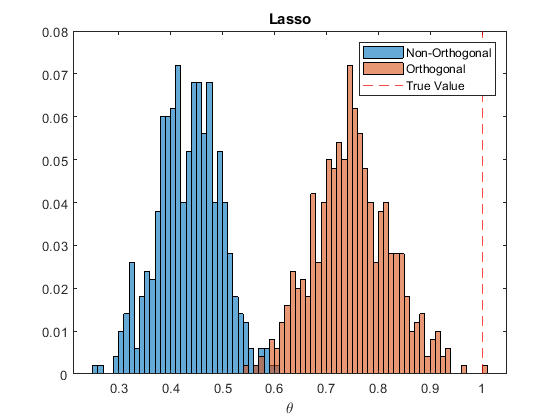

histogram(thetas_non_lasso, 'Normalization', 'probability', 'BinWidth', 0.01);
hold on
histogram(thetas_ort_lasso, 'Normalization', 'probability', 'BinWidth', 0.01);
xline(theta, '--r');
title('Lasso')
legend({'Non-Orthogonal','Orthogonal', 'True Value'})
xlabel('\theta')
hold off

thetas_non_rf = zeros(iters, 1);
thetas_ort_rf = zeros(iters, 1);

f = waitbar(0, '1', 'Name', 'Process Bar');

for iter = 1:iters
    waitbar(iter/iters, f, sprintf("%d / %d", [iter, iters]));

    rng(iter)
    X = randn(n, p);
    D = X(:, 1:3) * gamma + randn(n, 1);
    y = theta * D + X(:, 1:3) * beta + randn(n, 1);

    % Split main/auxiliary data
    cv = cvpartition(n, 'HoldOut', .5);
    idx = cv.test;
    XTrain = X(~idx, :); DTrain = D(~idx, :); yTrain = y(~idx, :);
    XTest = X(idx, :); DTest = D(idx, :); yTest = y(idx, :);

    % Estimate g
    ghat = fitrensemble(XTrain, yTrain, 'OptimizeHyperparameters', 'auto', ...
        'HyperparameterOptimizationOptions',struct('ShowPlots', false,...
        'Verbose', 0, 'MaxTime', 10, 'UseParallel', true));
    % Estimate m
    mhat = fitrensemble(XTrain, DTrain, 'OptimizeHyperparameters', 'auto', ...
        'HyperparameterOptimizationOptions',struct('ShowPlots', false,...
        'Verbose', 0, 'MaxTime', 10, 'UseParallel', true));

    % Plug-in method
    temp = mean(DTest .^ 2) ^ (-1) * mean(DTest .* (yTest - predict(ghat, XTest)));
    thetas_non_rf(iter) = temp;
    % Orthogonal method
    vhat = DTest - predict(mhat, XTest);
    temp = mean(DTest .* vhat) ^ (-1) * mean(vhat .* (yTest - predict(ghat, XTest)));
    thetas_ort_rf(iter) = temp;
end

close(f)

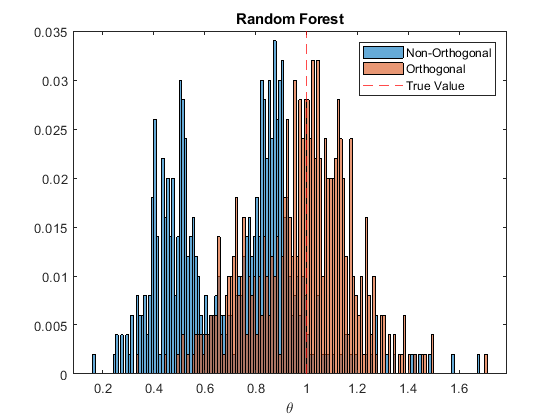

histogram(thetas_non_rf, 'Normalization', 'probability', 'BinWidth', 0.01);
hold on
histogram(thetas_ort_rf, 'Normalization', 'probability', 'BinWidth', 0.01);
xline(theta, '--r');
title('Random Forest')
legend({'Non-Orthogonal','Orthogonal', 'True Value'})
xlabel('\theta')
hold off

## Full Sample v.s Split Sample

K = 2;

thetas_full_lasso = zeros(iters, 1);
thetas_split_lasso = zeros(iters, 1);

f = waitbar(0, '1', 'Name', 'Process Bar');

for iter = 1:iters
    waitbar(iter/iters, f, sprintf("%d / %d", [iter, iters]));

    rng(iter)
    X = randn(n, p);
    D = X(:, 1:3) * gamma + randn(n, 1);
    y = theta * D + X(:, 1:3) * beta + randn(n, 1);

    %% Full sample
    % Estimate g
    [B, FitInfo] = lasso(X, y, 'CV', 10);
    idxLambda1SE = FitInfo.Index1SE;
    coef = B(:, idxLambda1SE);
    coef0 = FitInfo.Intercept(idxLambda1SE);
    ghat = X * coef + coef0;
    % Estimate m
    [B, FitInfo] = lasso(X, D, 'CV', 10);
    idxLambda1SE = FitInfo.Index1SE;
    coef = B(:, idxLambda1SE);
    coef0 = FitInfo.Intercept(idxLambda1SE);
    mhat = X * coef + coef0;
    % Orthogonal method
    v = D - mhat;
    temp = mean(D .* v) ^ (-1) * mean(v .* (y - ghat));
    thetas_full_lasso(iter) = temp;

    %% Split Sample
    temp = zeros(K, 1);
    cv = cvpartition(n, 'KFold', K);
    for i=1:cv.NumTestSets
        idx = cv.test(i);
        XTrain = X(~idx, :); DTrain = D(~idx, :); yTrain = y(~idx, :);
        XTest = X(idx, :); DTest = D(idx, :); yTest = y(idx, :);
        % Estimate g
        [B, FitInfo] = lasso(XTrain, yTrain, 'CV', 10);
        idxLambda1SE = FitInfo.Index1SE;
        coef = B(:, idxLambda1SE);
        coef0 = FitInfo.Intercept(idxLambda1SE);
        ghat = XTest * coef + coef0;
        % Estimate m
        [B, FitInfo] = lasso(XTrain, DTrain, 'CV', 10);
        idxLambda1SE = FitInfo.Index1SE;
        coef = B(:, idxLambda1SE);
        coef0 = FitInfo.Intercept(idxLambda1SE);
        mhat = XTest * coef + coef0;
        % Orthogonal method
        vhat = DTest - mhat;
        temp(i) = mean(DTest .* vhat) ^ (-1) * mean(vhat .* (yTest - ghat));
    end
    thetas_split_lasso(iter) = mean(temp);
end

close(f)

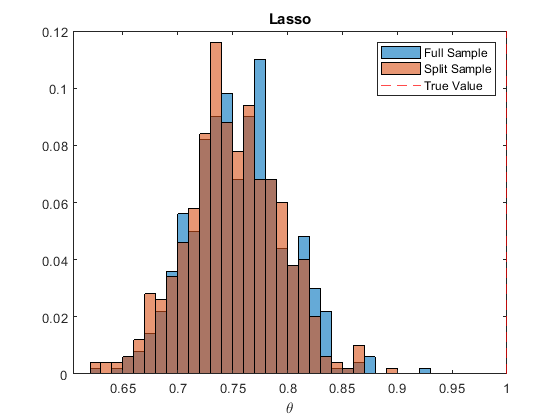

histogram(thetas_full_lasso, 'Normalization', 'probability', 'BinWidth', 0.01);
hold on
histogram(thetas_split_lasso, 'Normalization', 'probability', 'BinWidth', 0.01);
xline(theta, '--r');
title('Lasso')
legend({'Full Sample', 'Split Sample', 'True Value'})
xlabel('\theta')
hold off

K = 2;

thetas_full_rf = zeros(iters, 1);
thetas_split_rf = zeros(iters, 1);

f = waitbar(0, '1', 'Name', 'Process Bar');

for iter = 1:iters
    waitbar(iter/iters, f, sprintf("%d / %d", [iter, iters]));

    rng(iter)
    X = randn(n, p);
    D = X(:, 1:3) * gamma + randn(n, 1);
    y = theta * D + X(:, 1:3) * beta + randn(n, 1);

    %% Full sample
    % Estimate g
    ghat = fitrensemble(X, y, 'OptimizeHyperparameters', 'auto', ...
        'HyperparameterOptimizationOptions',struct('ShowPlots', false,...
        'Verbose', 0, 'MaxTime', 30));
    % Estimate m
    mhat = fitrensemble(X, D, 'OptimizeHyperparameters', 'auto', ...
        'HyperparameterOptimizationOptions',struct('ShowPlots', false,...
        'Verbose', 0, 'MaxTime', 30));
    % Orthogonal method
    vhat = D - predict(mhat, X);
    temp = mean(D .* vhat) ^ (-1) * mean(vhat .* (y - predict(ghat, X)));
    thetas_full_rf(iter) = temp;

    %% Split Sample
    temp = zeros(K, 1);
    cv = cvpartition(n, 'KFold', K);
    for i=1:cv.NumTestSets
        idx = cv.test(i);
        XTrain = X(~idx, :); DTrain = D(~idx, :); yTrain = y(~idx, :);
        XTest = X(idx, :); DTest = D(idx, :); yTest = y(idx, :);
        % Estimate g
        ghat = fitrensemble(XTrain, yTrain, 'OptimizeHyperparameters', 'auto', ...
            'HyperparameterOptimizationOptions',struct('ShowPlots', false,...
            'Verbose', 0, 'MaxTime', 10, 'UseParallel', true));
        % Estimate m
        mhat = fitrensemble(XTrain, DTrain, 'OptimizeHyperparameters', 'auto', ...
            'HyperparameterOptimizationOptions',struct('ShowPlots', false,...
            'Verbose', 0, 'MaxTime', 10, 'UseParallel', true));
        % Orthogonal method
        vhat = DTest - predict(mhat, XTest);
        temp(i) = mean(DTest .* vhat) ^ (-1) * mean(vhat .* (yTest - predict(ghat, XTest)));
    end
    thetas_split_rf(iter) = mean(temp);
end

close(f)

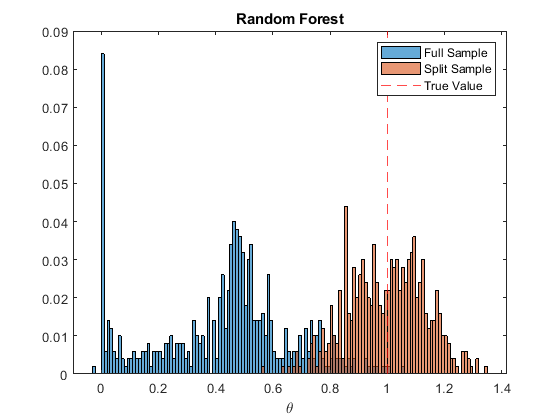

histogram(thetas_full_rf, 'Normalization', 'probability', 'BinWidth', 0.01);
hold on
histogram(thetas_split_rf, 'Normalization', 'probability', 'BinWidth', 0.01);
xline(theta, '--r');
title('Random Forest')
legend({'Full Sample', 'Split Sample', 'True Value'})
xlabel('\theta')
hold off